# Radiation Project

by 工物 00 Dait, YPWang

我们设计了一个可用于辐射防护及其他核物理学科的模块包。可以很大的方便解决辐射防护学科的相关问题以及数据查询。

这个模块包包含三个封装好的类：SI 类、Nuclide 类、Material 类

## SI 类

`SI` 类即国际单位制类，给出了一些**常用物理常量**在国际单位制下的值

SI.c

ans = 299792458

ref: NIST physic constants [https://physics.nist.gov/cuu/Constants/index.html](https://physics.nist.gov/cuu/Constants/index.html)

### 单位系统

`value = SI.unitv(expr)` 

解决这样一个问题：1 expr = ? in basic SI units.

SI.unitv('eV') % 1 eV = ? J

ans = 1.6022e-19

不仅支持前缀 M, k, m, u, n，也支持一些常用单位：

0.511 * SI.unitv('MeV/c2') % m_e

ans = 9.1094e-31

SI.me

ans = 9.1094e-31

单位表达式可能比较复杂，为方便规定：输入格式需要用 `'.' `连接各单位，但斜杠 `'/' `仅出现至多一次（其中质量单位 `'eV/c2'` 的斜杠不计入内）

SI.unitv('nSv/h.cm3')

ans = 2.7778e-07

`factor = SI.unit2v(old, new)` 

解决这样一个问题：1 old = ? new.

SI.unit2v('kcal', 'TeV') % 1 kcal = ? TeV

ans = 2.6132e+10

设计单位转换函数的意义在于：一般的代码中的变量并不包含单位信息，但在核物理尤其是辐射防护学科中，**经验公式非常多**，而其中的物理量单位必须指定。因此 SI 类的单位设计可以让用户重视单位问题，并**避免在代码中出现魔数**，方便他人理解代码。

ref: NIST International System of Units (SI) [https://physics.nist.gov/cuu/Units/index.html](https://physics.nist.gov/cuu/Units/index.html)

## Nuclide 类

`Nuclide` 类有如下属性：`Z, A, N, AX, Decay`；

可以通过符号构造 `Nuclide` 对象：

Rn222 = Nuclide('Rn-222') % or '222Rn'

Rn222 =   Nuclide - 属性:

        Z: 86
        A: 222
        N: 136
       AX: "222Rn"
    Decay: [1×1 struct]


`Decay` 是一个结构体，包含核素作为母核的衰变信息：能级、自旋宇称、衰变半衰期、衰变模式、强度、释放能量、子核。

Rn222.Decay

ans = 包含以下字段的 struct :
       Elevel: 0
          Jpi: "0+"
        Thalf: 3.3024e+05
         mode: "alpha"
    Intensity: 1
        GSGSQ: 5.5904e+03
     daughter: "218Po"
        gamma: [7×3 double]


这些数据均爬取自 NIST 的 [https://www.nndc.bnl.gov/nudat3/DecayRadiationServlet?nuc=222Rn&unc=NDS](https://www.nndc.bnl.gov/nudat3/DecayRadiationServlet?nuc=222Rn&unc=NDS)

特别的，有些衰变还有 $\beta$ 射线信息：平均能量 `E`、强度 `I`、剂量 `D`：

Nuclide('90Sr').Decay.beta

ans = 包含以下字段的 struct :
    E: 195.7000
    I: 1
    D: 0.1960


和 X, $\gamma$ 射线信息，每一列分别代表：能量 `E`、强度 `I`、剂量 `D`

Rn222.Decay.gamma(1 : 3, :)

ans =    11.1000    0.0400    0.0000
   76.8630    0.0400    0.0000
   79.2900    0.0400    0.0000


### 元素符号、原子序数

`[Z, A, N, X] = atomicNum(AX)`

根据元素符号获得原子序数 `Z`、核子数 `A`、中子数 `N` 等

Nuclide.atomicNum(["131I", "137cs", "40K", "32S", "16O"])

ans =     53
    55
    19
    16
     8


注：根据原子序数获得元素符号可通过 `Material.element.symbol(Z)`

### 核素数据

使用 `Nuclide` 的静态方法获得核素数据：比结合能、原子质量、半衰期、$\alpha$ 衰变能、$\beta^-$ 衰变能、$\beta^+$ 衰变能、EC 衰变能等

输入：核素符号（字符串数组）、单位（可选）

Nuclide.Thalf(["222Rn", "210Pb"], 'd') % default second

ans = 1.0e+03 *

    0.0038
    8.1085


Nuclide.mass('12C', 'u')

ans = 12.0000

### 衰变链

`[I, T] = Nuclide(AX).decayChain(options)`

利用衰变信息的子核符号，可以得到子核的衰变信息，并将子核作为下一代母核继续衰变得到子核，以此递推，直到所有子核都没有衰变信息。

为了将衰变链清晰地展现出来，我们利用有向图展示衰变过程：

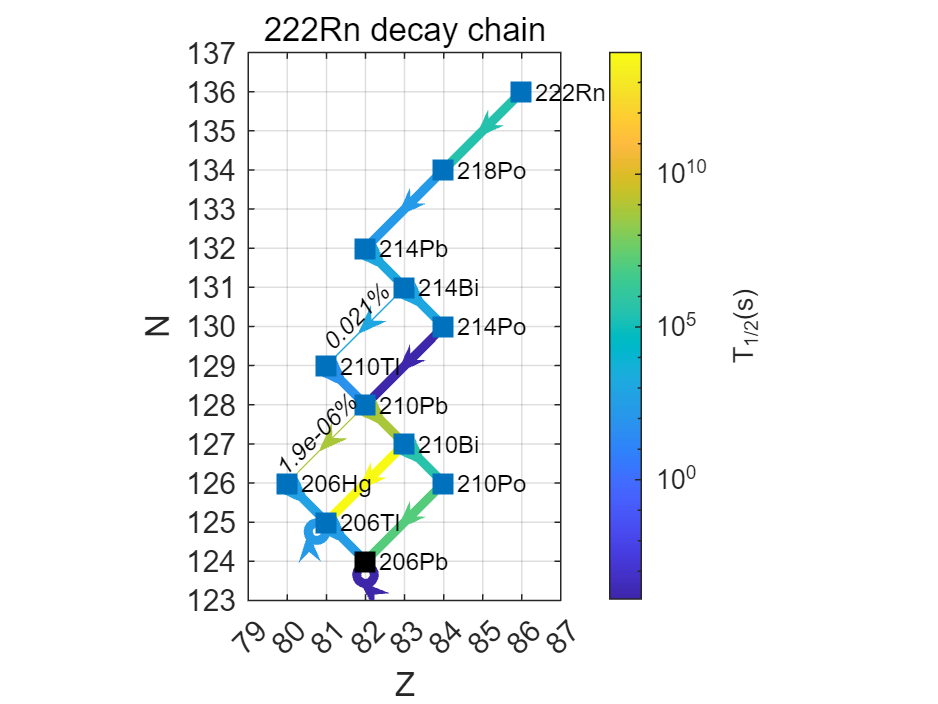

Rn222.decayChain();

上图每个格点都代表一个核素，黑色的节点表示没有衰变信息（特指不产生子核的衰变，即不包括同质异能跃迁 IT）；线条的粗细表示衰变强度，并标出了小于 99% 的强度值；线条的颜色代表衰变半衰期，不同核素之间半衰期差别非常大，故 `colorbar` 采用了对数坐标。从上图可以看出，左下箭头表示 $\alpha$ 衰变，右下箭头表示 $\beta {\;}^-$ 衰变，自环表示同质异能跃迁（IT）。

210Pb 的半衰期（22.2 年）远大于 222Rn 的半衰期（3.6 天），因此可以添加几个阈值简化衰变链：

- 半衰期阈值 `Tstable`：半衰期高于此阈值即可认为是稳定核；

- 强度阈值 `Imin`：强度低于此阈值即可忽略。

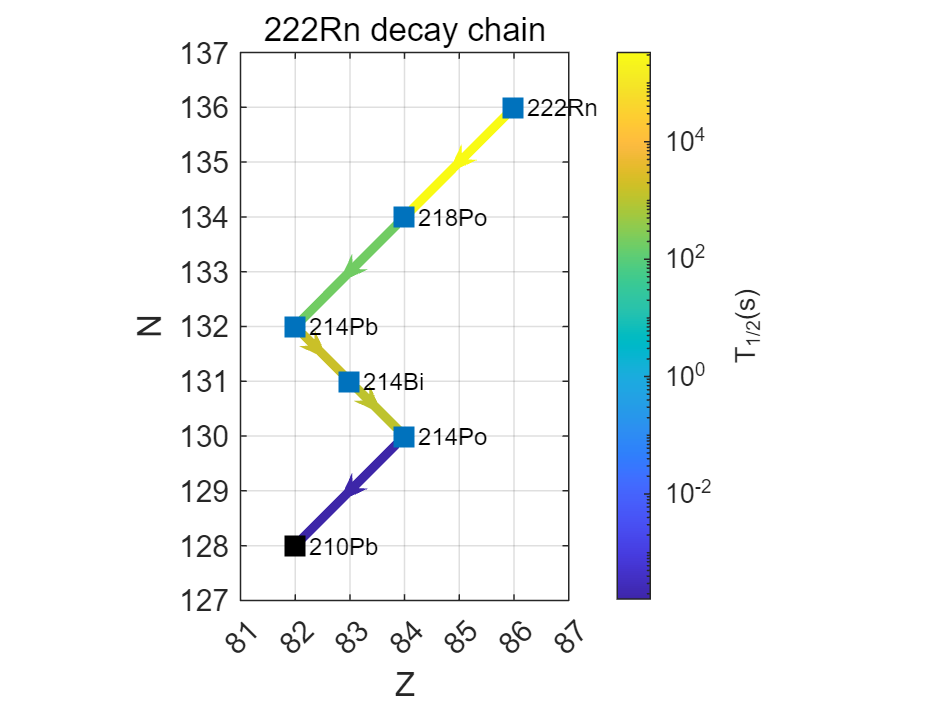

Rn222.decayChain(Tstable=1e8, Imin=0.1);

`obj.DecayChain()` 可以输出有向图的邻接矩阵 `I, T`。以 `I` 为例，其意义为：若 $I_{\textrm{ij}} \;\not= \;0$，则表示节点 i 连接到节点 j，且其值表示有向边的权重。我们分别用强度和半衰期表示权重。

### 衰变动力学

`[t, n, AXs] = Nuclide(AX).decayDynamic(tspan, n0, options)`

我们可以利用衰变链的衰变信息得到核素的衰变动力学过程，


$$\frac{\mathrm{d}}{\mathrm{d}t}N_j =-\sum_k^{\textrm{child}} I_{\textrm{jk}} \lambda_{\textrm{jk}} N_j +\sum_i^{\textrm{parent}} I_{\textrm{ij}} \lambda_{\textrm{ij}} N_i$$


$I_{ij},\lambda_{ij}$ 表示从 i 核衰变到 j 核的强度、衰变常数。因此偏微分方程的矩阵可以用邻接矩阵推导出来：

% lambda = log(2) ./ T;
% lambda(isinf(lambda)) = 0; % T_ij = 0, lambda_ij = 0
% A = (lambda .* I)';
% A = A - diag(sum(A));

这样便可以表示成矩阵形式


$$\frac{\mathrm{d}}{\mathrm{d}t}N=\textrm{AN},$$


因此解此偏微分方程是容易的，除了直接输出 `n, t` 数据，`obj.decayDynamic` 还额外配备了画图选项：

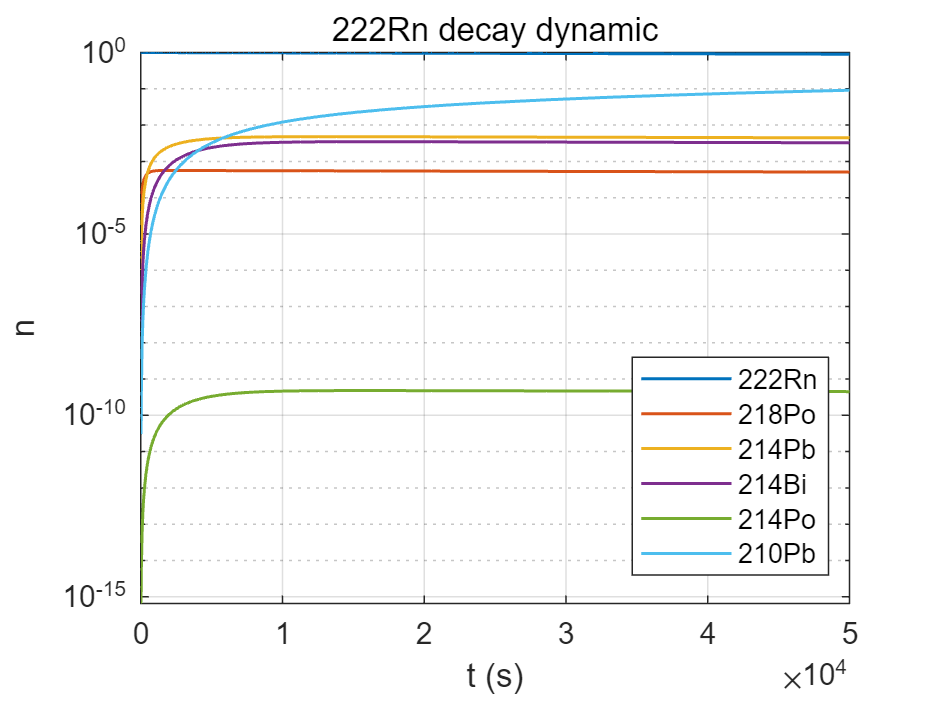

[t, n] = Rn222.decayDynamic([0 5e4], [], Tstable=1e8, Imin=0.1, plotN=true);

### PAE, PAEC, EEC

`Nuclide` 类也可以解决**氡的相关问题**。

#### $\alpha$ 潜能（PAE）

`ep = Nuclide.PAE(N_RnDP, A_Rn)` 

算法很简单，就是对氡子体数量的简单加权，如果有 N 组氡子体数据排列成 N x 4 的矩阵，则可以用矩阵乘法方便地计算。

N_RnDP = 1e5 * n(:, 2 : 5);
ep = N_RnDP * ([Nuclide.Talpha("218Po"); 0; 0; 0] + Nuclide.Talpha("214Po"));

除了 222Rn，也可以处理 220Rn 和 219Rn 的 $\alpha$ 潜能计算。

结合上述的衰变动力学，我们可以简单模拟氡衰变过程中 $\alpha$ 潜能的变化

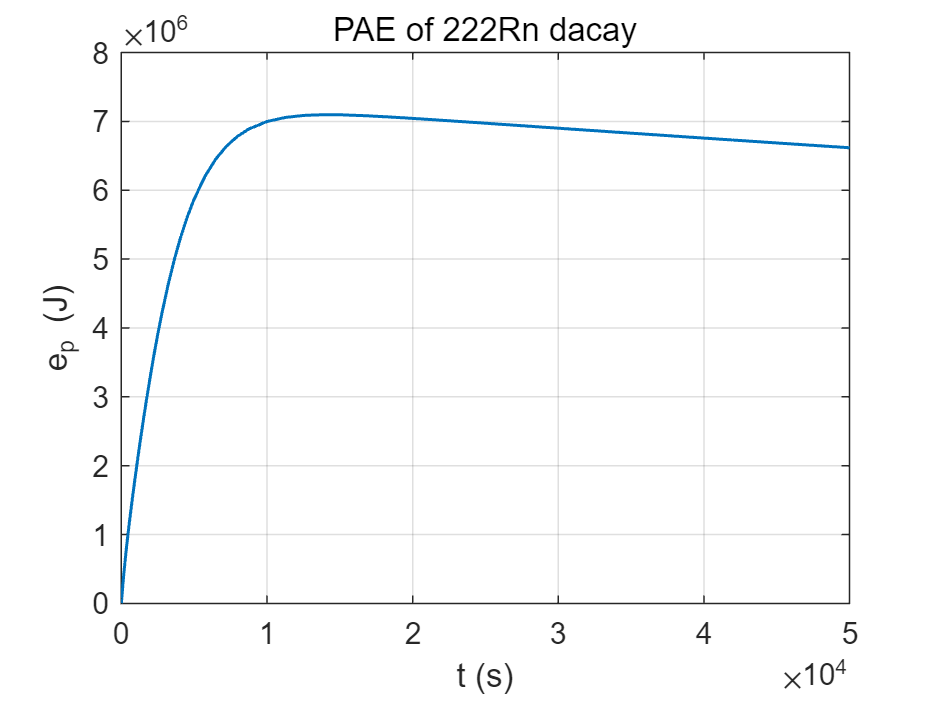

plot(t, ep, LineWidth=1)
grid on
title('PAE of 222Rn dacay')
xlabel('t (s)')
ylabel('e_p (J)')

#### $\alpha$ 潜能浓度

`cp = Nuclide.PAEC(c_RnDP, A_Rn)`

所用的参数是活度浓度，利用活度关系 $A=\lambda N$ 即可

#### 平衡当量浓度

`ceq = Nuclide.EEC(c_RnDP, A_Rn)`

的算法也很简单：

% ceq = Nuclide.PAEC(c_RnDP) ./ Nuclide.PAEC(ones(1, 4));

## Material 类

`Material` 类中有两个常量属性：`element` 和 `compound`，这两个结构体中包含了 300 种常见的单质、化合物和混合物。

`element` 存储了前 98 个元素（区分碳单质 `C` 和石墨 `graphite`），可直接通过元素符号索引：

Material.element.Al

ans = 包含以下字段的 struct :
    fullname: "Aluminum"
           Z: 13
           I: 166
         rho: 2.6989
         ZPA: 0.4818
         Xmu: [38×3 double]
       ESTAR: [81×7 double]
       PSTAR: [133×7 double]
       ASTAR: [122×7 double]


`Z` 为原子序数，`I` 为平均激发能，`rho` 为单质密度，`ZPA` 为质子数 / 核子数，

`Xmu` 为 X 射线的衰减系数数据，

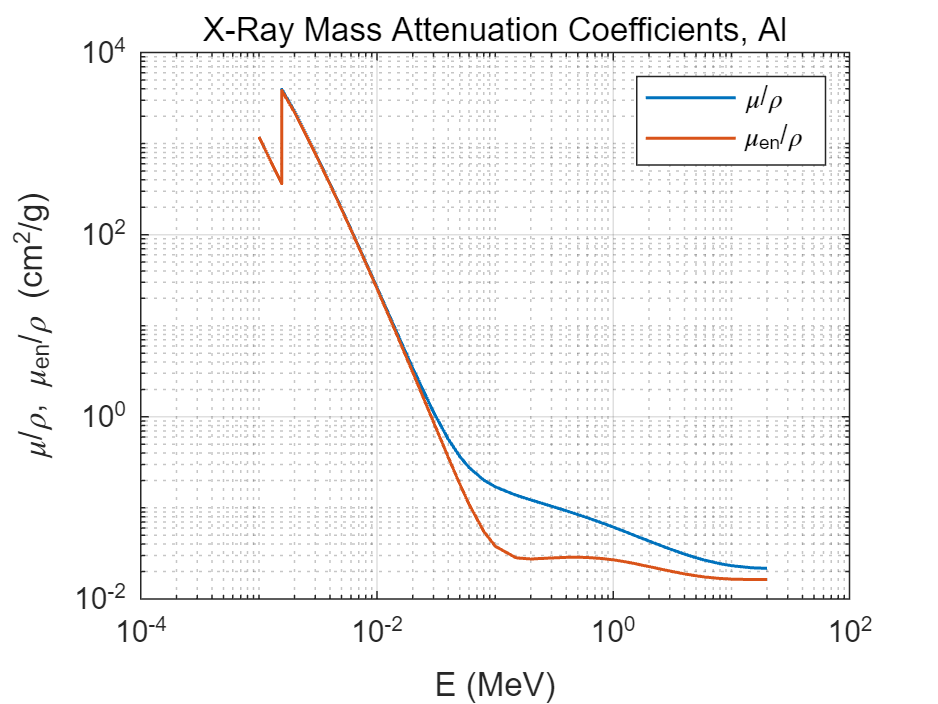

EXMU = Material.element.Al.Xmu;
loglog(EXMU(:, 1), EXMU(:, 2), ...
    EXMU(:, 1), EXMU(:, 3), 'LineWidth', 1)
grid on
title('X-Ray Mass Attenuation Coefficients, Al')
xlabel('E (MeV)')
ylabel('\mu/\rho, \mu_{en}/\rho (cm^2/g)')
legend('\mu/\rho', '\mu_{en}/\rho')

clear EXMU

衰减系数来源于 NIST 的 [https://physics.nist.gov/PhysRefData/XrayMassCoef/ElemTab/z13.html](https://physics.nist.gov/PhysRefData/XrayMassCoef/ElemTab/z13.html)

`ESTAR, PSTAR, ASTAR` 是对电子、质子、$\alpha \;$粒子的阻止本领和射程等数据。

Material.element.Al.ESTAR(1 : 3, :)

ans =     0.0100   16.4900    0.0066   16.5000    0.0004    0.0002    0.0004
    0.0125   13.9800    0.0067   13.9800    0.0005    0.0003    0.0005
    0.0150   12.2000    0.0068   12.2100    0.0007    0.0003    0.0007


阻止本领和射程等数据来源于 NIST 的：

- [https://physics.nist.gov/PhysRefData/Star/Text/ESTAR.html](https://physics.nist.gov/PhysRefData/Star/Text/ESTAR.html)

- [https://physics.nist.gov/PhysRefData/Star/Text/PSTAR.html](https://physics.nist.gov/PhysRefData/Star/Text/PSTAR.html)

- [https://physics.nist.gov/PhysRefData/Star/Text/ASTAR.html](https://physics.nist.gov/PhysRefData/Star/Text/ASTAR.html)

`compound` 存储了 200 多种化合物和混合物，他们均可看成多种元素的加权组合，

Material.compound.air

ans = 包含以下字段的 struct :
       fullname: "Air, Dry (near sea level)"
              I: 85.7000
            rho: 0.0012
    composition: [4×2 double]
            ZPA: 0.4992
          ESTAR: [81×7 double]
          PSTAR: [133×7 double]
          ASTAR: [122×7 double]


`composition` 是组成元素及质量分数

Material.compound.air.composition

ans =     6.0000    0.0001
    7.0000    0.7553
    8.0000    0.2318
   18.0000    0.0128


如果希望在已有的物质信息中查询所需物质，仅需在 `Material.search()` 中输入关键词

Material.search('CO')

element:
    {'Co'}

compound:
    {'bone_compact'     }
    {'bone_cortical'    }
    {'CaCO3'            }
    {'CO2'              }
    {'concrete_portland'}
    {'glucose'          }
    {'Li2CO3'           }
    {'MgCO3'            }
    {'Na2CO3'           }
    {'CONH2_2'          }
    {'concrete_ordinary'}
    {'concrete_barite'  }



### X, γ 射线衰减系数

`[mu, muen] = Material.Xmu(E, Z, fraction)`

`Material` 类配备了求任意物质的任意能量 `E` 的 X, γ 射线衰减系数方法

Material.Xmu([0.511 0.662], Material.compound.air)

ans =     0.0865
    0.0769


如果希望使用 `Material` 中没有的物质，只需定义一个结构体，其中包含 `Z` 或 `composition` 即可。

### 阻止本领和射程

`[Sc, Sr, St, Rc, Y, Erho] = Material.ESTAR(T, Z, fraction)`

`[Se, Sn, St, Rc, Rp, detour] = Material.PSTAR(T, Z, fraction)`

`[Se, Sn, St, Rc, Rp, detour] = Material.ASTAR(T, Z, fraction)`

输入：粒子动能 `T` 和物质；

输出：

碰撞阻止本领 `Sc`、辐射阻止本领 `Sr`、总阻止本领 `St`、射程 `Rc`、辐射产量 `Y`、密度效应 `Erho`

电子阻止本领 `Se`、核阻止本领 `Sn`、总阻止本领 `St`、射程 `Rc`、预计射程 `Rp`、迂回系数 `detour = Rp / Rc`

## **其他辅助函数**

### **中子辐射权重因子 wRn**

`w_n = Material.wRn(En)`

用于计算特定能量中子对应的辐射权重因子。计算公式来源于 ICRP 92 号出版物：


$$w_n ={\left\{\begin{array}{cc}
2.5+18.2\;\exp \left\lbrack -\ln \left(E_n \right)/6\right\rbrack  & E_n <1\;\textrm{MeV}\\
5.0+17.0\;\exp \left\lbrack -\ln \left(2E_n \right)/6\right\rbrack  & 1\;\textrm{MeV}\le E_n \le 50\;\textrm{MeV}\\
2.5+3.25\;\exp \left\lbrack -\ln \left({0\ldotp 04E}_n \right)/6\right\rbrack , & E_n >50\;\textrm{MeV}
\end{array}\right)}$$


实例

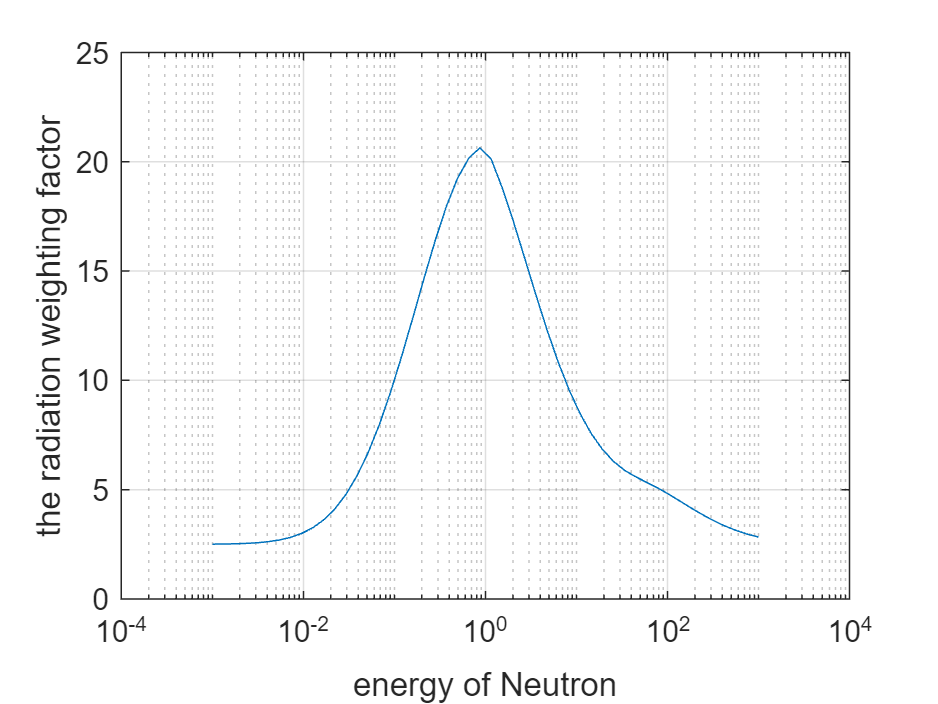

E_n = logspace(-3, 3); 
w_n = Material.wRn(E_n); 
semilogx(E_n, w_n); 
xlabel('energy of Neutron')
ylabel('the radiation weighting factor')
grid on

clear E_n w_n

### **康普顿散射计算**

`[hv_, E, psi] = SI.Compton(hv, theta, m, options)`

用于计算康普顿散射光子能量、反冲电子能量、反冲角。

其中 `hv` 为入射光子能量（MeV）、`theta` 为质心系下的散射角、`m` 为核的质量（MeV/c2），默认为电子。各种核的质量可于 `SI` 类或 `Nuclide` 类种查到。

比如 137Cs 的 0.662 MeV $\gamma$射线与电子的康普顿散射。

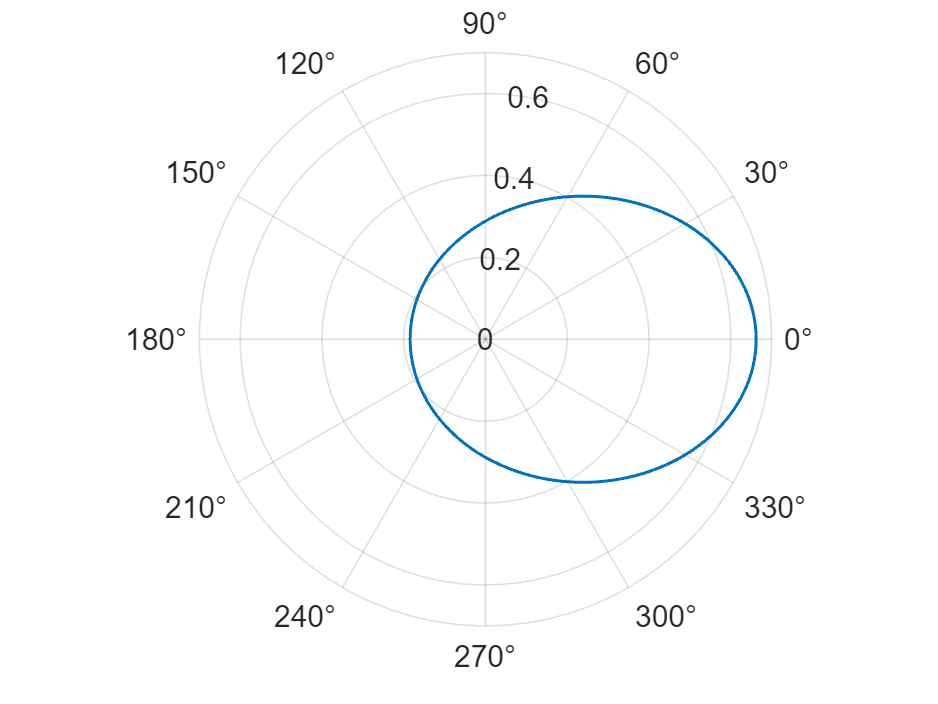

polarplot(SI.Compton(0.662, 0 : 360), ...
    LineWidth=1)

#### $\beta
$ 屏蔽计算

`[t1, t2] = Nuclide(AX).betaShield(A, m1, m2, D, R1, R, m0)`

`[t1, t2] = Material.betaShield(A, Emax, Emean, m1, m2, D, R1, R, m0)`

基于 Material 类的实用函数，用于计算双层 $\beta
$ 屏蔽时，屏蔽层厚度。

待输入参数为源活度（A）、电子最大能量（Emax）、电子平均能量（Emean）、内外两层屏蔽材料（m1, m2）、目标最大剂量率Sv/s（D）、屏蔽层与源的距离（R1）、目标与源的距离（R）、介质材料（m0）默认为真空。三种材料的输入类型均为 Material 类中的材料。

比如课件中的问题：内层有机玻璃（PMMA）、外层铅

[t1, t2] = Material.betaShield(1.85e11, 2.18, 0.73, ...
    Material.compound.PMMA, Material.element.Pb, ...
    2.5e-2 * SI.unitv('mGy/h'), 20, 40)

t1 = 1.1128

t2 = 3.2593

#### 洛文格（Lovinger）公式

`dotD = Nuclide(AX).Lovinger(A, medium, d)`

`dotD = Material.Lovinger(A, Emax, Emean, medium, d, options)`

基于 Material 类的实用函数，用于计算空气或软组织对 $\beta
$ 点源的吸收剂量。

待输入参数为源活度（A）、电子最大能量（Emax）、电子平均能量（Emean）、吸收介质的距离深度（d），吸收介质（medium）。其中吸收介质必须为Material类中的空气（air）或组织（tissue），输出单位默认为（mGy/h）。

也可以通过Nuclide类指定核素代替电子平均能量和最大能量。

dotD = Nuclide('P32').Lovinger(SI.unitv('Ci'), Material.compound.air, 30.5)

dotD = 3.6857e+03

## 代码可扩展性

面向对象设计，**对修改关闭、对扩展开放。**用户可以在不修改已有代码的情况下扩展功能。

比如在 `mySI.m` 中定义了一个自己设计的新类 `mySI`，继承了 `SI` 类，也定义了新的常量 `mmu` 即 $\mu \;$子质量，

mySI.mmu

ans = 1.8835e-28

新的 `mySI` 类拥有 `SI` 类所有的 `public` 和 `protected` 功能：

mySI.c

ans = 299792458

mySI.unitv('kW.h')

ans = 3600000